## Arizona Eye Model

Initialize the eye-model in relaxed state and display it a table. Distances are in mm.

y = 3;  % 3-mm semi-diameter for all optics
A = 0;  % Diopters of accommodation
arizonaEye = OpticalSystem();
arizonaEye.addSurface("Cornea", 7.8, 0.55, 1.377, y, -0.25)
arizonaEye.addSurface("Aqueous", 6.5, 2.97 - 0.04*A, 1.337, y, -0.25)
arizonaEye.addSurface("Lens", 12.0 - 0.4*A, 3.767 + 0.04*A,...
    1.42 + 0.00256*A - 0.00022*A^2, y, -7.518749 + 1.285720*A)
arizonaEye.addSurface("Vitreous", -5.224557 + 0.2*A, 16.713, 1.336,...
    y, -1.353971 - 0.431762*A)
arizonaEye.updateLastSurface("Retina", -13.4, 0, 1j*inf, y, 0)
disp(arizonaEye.lensData)

Compute back focal length

Start by tracing ray from OBJ to Retina

%M = arizonaEye.rayMatrix(1,2);
% if T.Thickness < eps, start right at the cornea
arizonaEye.lensDataReverse

y0 = [1; 0];
T = arizonaEye.lensData;

M = eye(2);
for s = 1:4
    d = T.Thickness(s);
    r = T.Radius(s+1);
    n1 = real(T.Index(s));
    n2 = real(T.Index(s+1));
    M = [1 0; (1/r)*(n1/n2 - 1) n1/n2]*[1 d; 0 1]*M;
end
y =M*y0;
bfl = -y(1) / tan(y(2))
f = -1 / tan(y(2)) / n2;
1000 / f

Draw the eye

## Radial Power Profile

Normalize pupil coordinate to max pupil-size of 6 mm

clearvars
pupilSize = 6;

Fit Zernike power polynomials to a given aspheric power profile which made up of defocus and 1 or more orders of spherical aberration (SA)


$$P(r)=\frac{1}{r} \frac{\partial W(r) }{\partial r}$$


r = [0.0, 0.275, 0.503, 0.677, 0.834, 1.0, 1.165, 1.284, 1.418, 1.599, 1.756, 1.865, 1.935,...
    2.0, 2.052, 2.098, 2.129, 2.16, 2.2, 2.22, 2.25]';
P = [20.0, 20.043, 20.16, 20.3, 20.467, 20.666, 20.87, 21.02, 21.15, 21.25, 21.1755, 21.0,...
    20.79, 20.56, 20.288, 20.05, 19.81, 19.61, 19.27, 19.04, 18.78]';

Normalized pupil eccentricity$\rho = \frac{r}{a}$ where $a$ is pupil radius (mm) 

a = 0.5 * pupilSize;
rho = r / a;

Zernike terms for defocus, 4th-order and 6th-order SA. Top term is the ANSI standard, and bottom term is the ANSI standard's corresponding power profile 


$$ Z_4(\rho) =  \begin{cases}
c_4 \sqrt3 (2 \rho ^2 - 1) \\
\frac{4\sqrt3}{a^2} c_4 \end{cases}$$



$$ Z_{12}(\rho) =  \begin{cases}
c_{12} \sqrt5 (6\rho^4 - 6\rho^2 + 1) \\
\frac{ 12\sqrt5}{a^2} c_{12} (2 \rho^2-1) \end{cases}$$


Corneal SA for 6-mm pupil is 0.27 ± 0.02 μm on average


$$ Z_{24}(\rho) =  \begin{cases}
c_{24} \sqrt7 (20\rho^6 - 30\rho^4 + 12\rho^2 - 1) \\
\frac{24\sqrt7}{a^2} c_{24} (5\rho^4 - 5\rho^2 + 1) \end{cases}$$


M = [ones(length(P),1) * 4*sqrt(3)/(a/1e3)^2 ... % defocus
    (2*rho.^2 - 1) * 12*sqrt(5)/(a/1e3)^2 ... % 4th-order SA
    (5*rho.^4 - 5*rho.^2 + 1) * 24*sqrt(7)/(a/1e3)^2]; % 6th-order SA
c = M \ P; % coefficients in meters
disp(c(2:3) * 1e6)

   -1.9706
   -0.6680



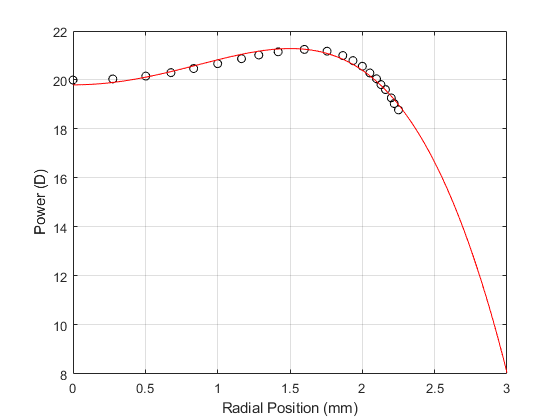

rho_ = (0:0.01:1)';
P_ = c(1) * 4 * sqrt(3) / (a/1e3)^2 + ...
    (c(2) * 12 * (sqrt(5) / (a/1e3)^2)) * (2*rho_.^2 - 1) + ...
    (c(3) * 24 * (sqrt(7) / (a/1e3)^2)) * (5*rho_.^4 - 5*rho_.^2 + 1);

r_ = rho_ * a;
plot(r, P, 'ok'), grid on
hold on, plot(r_, P_, "r"), hold off
xlabel("Radial Position (mm)"), ylabel("Power (D)")
xlim([0 3])